# Stability Criteria

Rover shall be designed to safely accommodate a 20° slope in any direction at a speed of at least 1 m/sec and including the ability to start and stop.

## Parameters

Slope $\theta =20$ degrees

Mass $m = 670$ kg

Gravity $g = 1.62 \frac{m}{s^2{$ 

r = wheel radius (m)

h = height (m) between the wheel axes and CoM

l = length (m) between the front and rear axles

a = length (m) between the front axle and CoM

ax = longitudinal acceleration $\frac{m}{s^2}$

## Longitudinal Dynamic Stability


$$N_1 = mg\bigg(\bigg(1-\frac{a}{l}\bigg)cos\theta-\bigg(\frac{h}{l}+\frac{r}{l}\bigg)sin\theta-\frac{a_x}{g}\bigg)$$



$$N_2 = mg\bigg(\frac{a}{l}cos\theta+\bigg(\frac{h}{l}+\frac{r}{l}\bigg)sin\theta+\frac{a_x}{g}\bigg)$$



$$T_1 = \frac{N_1}{N_1+N_2}(mgsin\theta+ma_x)$$



$$T_2 = \frac{N_2}{N_1+N_2}(mgsin\theta+ma_x)$$


clear vars
clc
close all

theta = deg2rad(20); % Slope (rad)
m = 670; %kg, total (max) rover mass
g = 1.62; %m/s^2, accel due to gravity on the Moon

syms h l ax a r slope

N1 = m*g*((1-(a/l))*cos(theta)-((h/l)+(r/l))*sin(theta)-(ax/g))/2; % Normal force (N) on each of the front two wheels
N2 = m*g*((a/l)*cos(theta)+((h/l)+(r/l))*sin(theta)-(ax/g))/2; % Normal force (N) on each of the rear two wheels
T_RR = (N2/(N1+N2))*m*g*sin(theta)+m*ax; % Torque (Nm) applied by the rear right wheel
T_RL = (N2/(N1+N2))*m*g*sin(theta)+m*ax; % Torque (Nm) applied by the rear left wheel
T_FR = (N1/(N1+N2))*m*g*sin(theta)+m*ax; % Torque (Nm) applied by the front right wheel
T_FL = (N1/(N1+N2))*m*g*sin(theta)+m*ax; % Torque (Nm) applied by the front left wheel

h_ =0.8;
l_ =2.4;
r_ =0.3;
a_ =1;
ax_=0.5;


N1_ = double(subs(N1,[h l ax a r],[h_ l_ ax_ a_ r_]))

N1_ = 44.9100

N2_ = double(subs(N2,[h l ax a r],[h_ l_ ax_ a_ r_]))

N2_ = 130.0612

T_F = double(subs(T_FR,[h l ax a r],[h_ l_ ax_ a_ r_]))

T_F = 430.2835

T_R = double(subs(T_RR,[h l ax a r],[h_ l_ ax_ a_ r_]))

T_R = 610.9452

### Graphs

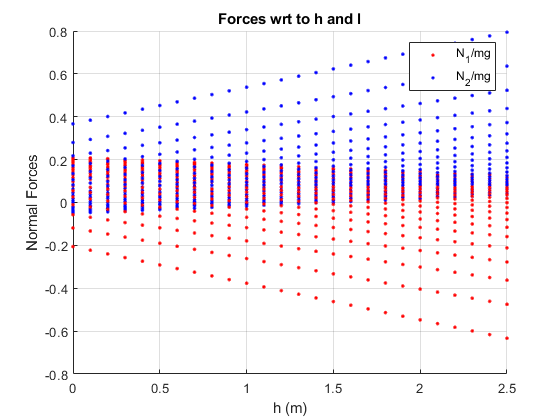

% 3D plot (h vs l vs normal forces)
slope1 = 20;
N1_list = [];
N2_list = [];
h_list = [];
l_list = [];

for h_trial = 0:0.1:2.5
    for l_trial = 1:0.2:5
          N1 = m*g*((1-(a_/l_trial))*cosd(slope1)-((h_trial/l_trial)+(r_/l_trial))*sind(slope1)-(ax_/g))/2;
          N2 = m*g*((a_/l_trial)*cosd(slope1)+((h_trial/l_trial)+(r_/l_trial))*sind(slope1)-(ax_/g))/2;  
          N1_norm = N1/(m*g);
          N2_norm = N2/(m*g);
          N1_list = [N1_list,N1_norm];
          N2_list = [N2_list,N2_norm];
          h_list=[h_list,h_trial];
          l_list=[l_list,l_trial];
    end
end
figure
hold on
plot3(h_list,l_list,N1_list,'.r')
plot3(h_list,l_list,N2_list,'.b')
xlabel('h (m)')
ylabel('l (m)')
zlabel('Normal Forces')
legend('N_1/mg','N_2/mg')
title('Forces wrt to h and l')
%[x,y] = meshgrid(0:0.1:2.5,1:0.1:6);
%z=0.*x+0.*y;
%surf(x,y,z,'FaceAlpha',0.1)
hold off
grid on
view (0,360)

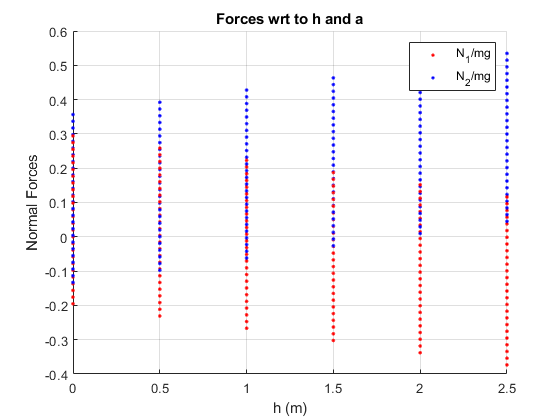


clear N1_list N2_list h_list l_list

% 3D plot (h vs a vs normal forces)
slope1 = 20;
N1_list = [];
N2_list = [];
h_list = [];
a_list = [];

for h_trial = 0:0.5:2.5
    for a_trial = 0:0.1:2.5
          N1 = m*g*((1-(a_trial/l_))*cosd(slope1)-((h_trial/l_)+(r_/l_))*sind(slope1)-(ax_/g))/2;
          N2 = m*g*((a_trial/l_)*cosd(slope1)+((h_trial/l_)+(r_/l_))*sind(slope1)-(ax_/g))/2;  
          N1_norm = N1/(m*g);
          N2_norm = N2/(m*g);
          N1_list = [N1_list,N1_norm];
          N2_list = [N2_list,N2_norm];
          h_list=[h_list,h_trial];
          a_list=[a_list,a_trial];
    end
end

figure
hold on
plot3(h_list,a_list,N1_list,'.r')
plot3(h_list,a_list,N2_list,'.b')
xlabel('h (m)')
ylabel('a (m)')
zlabel('Normal Forces')
legend('N_1/mg','N_2/mg')
title('Forces wrt to h and a')
%[x,y] = meshgrid(0:0.1:2.5,0:0.1:2.5);
%z=0.*x+0.*y;
%surf(x,y,z,'FaceAlpha',0.1)
hold off
grid on
view (0,360)

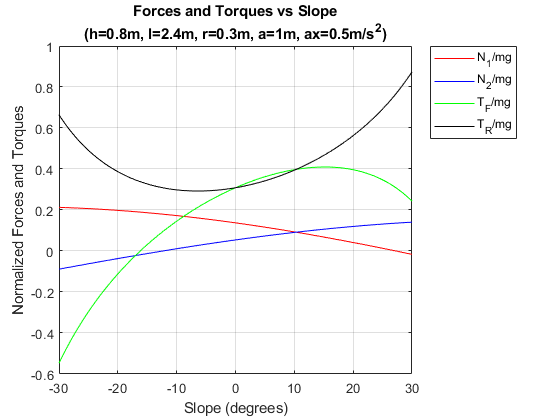

clear N1_list N2_list h_list a_list


% 2D plot
slope = -30:0.05:30;
N1_list = zeros(1,length(slope));
N2_list = zeros(1,length(slope));
T_R_list = zeros(1,length(slope));
T_F_list = zeros(1,length(slope));

for i = 1: length(slope)
    N1_list(i) = m*g*((1-(a_/l_))*cosd(slope(i))-((h_/l_)+(r_/l_))*sind(slope(i))-(ax_/g))/2;
    N2_list(i) = m*g*((a_/l_)*cosd(slope(i))+((h_/l_)+(r_/l_))*sind(slope(i))-(ax_/g))/2;
    T_F_list(i) = (N1_list(i)/(N1_list(i)+N2_list(i)))*m*g*sind(slope(i))+m*ax_;
    T_R_list(i) = (N2_list(i)/(N1_list(i)+N2_list(i)))*m*g*sind(slope(i))+m*ax_; 
end
plot(slope,N1_list./(m*g),'red')
hold on
plot(slope,N2_list./(m*g),'blue')
hold on
plot(slope,T_F_list./(m*g),'green')
hold on
plot(slope, T_R_list./(m*g), 'black')
hold off
legend('N_1/mg','N_2/mg','T_{F}/mg','T_{R}/mg')
xlabel('Slope (degrees)')
ylabel("Normalized Forces and Torques")
graph_title=strcat('(h=',num2str(h_),'m, l=',num2str(l_),'m, r=',num2str(r_),'m, a=',num2str(a_),'m, ax=',num2str(ax_),'m/s^2)');
title({'Forces and Torques vs Slope',graph_title})

grid on

### Overturn Limits

- For dynamic case:

#### 
$$(1-\frac{a}{l})cos{\theta_{limit}} - (\frac{h}{l}+\frac{r}{l})sin{\theta_{limit}} = \frac{a_x}{g}
$$


syms theta_l_d

eqn = ((1-(a_/l_))*cos(theta_l_d) - ((h_+r_/l_)*sin(theta_l_d)));
Theta_limit_d = rad2deg(double(solve(eqn,theta_l_d)))

Theta_limit_d =  -147.7632
   32.2368


- For static case: 


$$tan{\theta_{limit}} = \frac{l-a}{h+r}$$


syms theta_l_s
Theta_limit_s = rad2deg(atan((l_-a_)/(h_+r_)))

Theta_limit_s = 51.8428

#### Limiting acceleration on flat ground : $a_{x,limit} = g(1-\frac{a}{l})$

a_x_limit = g*(1-(a_/l_))

a_x_limit = 0.9450

### Limits on slope

- Acceleration :  

 
$$\frac{dv}{dt}\Bigr|_{lim} = g[(\frac{l-a}{r+h})cos{\theta} - sin{\theta}]$$


- Deceleration


$$\frac{dv}{dt}\Bigr|_{lim} =- g[(\frac{a}{r+h})cos{\theta} + sin{\theta}]$$


theta = 0:1:60;
dvdt_a = g*(((l_-a_)*cosd(theta)/(r_+h_)) - sind(theta));
Limited_Acceleration = [num2str(dvdt_a),'  m/s^2'];
disp(Limited_Acceleration)

2.0618      2.0332       2.004      1.9742      1.9438      1.9128      1.8812       1.849      1.8163       1.783      1.7492      1.7148      1.6799      1.6446      1.6087      1.5723      1.5354      1.4981      1.4603      1.4221      1.3834      1.3443      1.3048      1.2649      1.2247       1.184       1.143      1.1016      1.0599      1.0179     0.97559     0.93296     0.89005     0.84687     0.80343     0.75975     0.71583      0.6717     0.62736     0.58283     0.53813     0.49326     0.44824     0.40308      0.3578     0.31241     0.26693     0.22136     0.17573     0.13004    0.084319    0.038568  -0.0071954   -0.052956   -0.098701    -0.14442    -0.19009     -0.2357    -0.28124     -0.3267    -0.37205  m/s^2


dvdt_d = -g*(((a_)*cosd(theta)/(r_+h_)) + sind(theta));
Limited_Acceleration = [num2str(dvdt_d),'  m/s^2'];
disp(Limited_Acceleration)

-1.4727     -1.5008     -1.5284     -1.5555     -1.5821     -1.6083      -1.634     -1.6592     -1.6839      -1.708     -1.7317     -1.7548     -1.7774     -1.7994     -1.8209     -1.8418     -1.8622      -1.882     -1.9013     -1.9199      -1.938     -1.9555     -1.9724     -1.9886     -2.0043     -2.0194     -2.0338     -2.0477     -2.0609     -2.0735     -2.0854     -2.0967     -2.1074     -2.1174     -2.1268     -2.1356     -2.1437     -2.1511     -2.1579      -2.164     -2.1695     -2.1743     -2.1784     -2.1819     -2.1847     -2.1869     -2.1884     -2.1892     -2.1893     -2.1888     -2.1876     -2.1858     -2.1833     -2.1801     -2.1763     -2.1717     -2.1666     -2.1608     -2.1543     -2.1471     -2.1393  m/s^2


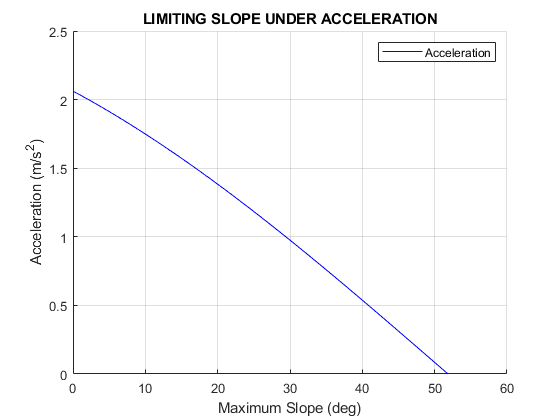

figure
hold on
plot(theta,dvdt_a,'blue')
hold off
xlabel('Maximum Slope (deg)')
ylabel("Acceleration (m/s^2)")
ylim([0 2.5])
grid on
title('LIMITING SLOPE UNDER ACCELERATION')
legend('Acceleration')

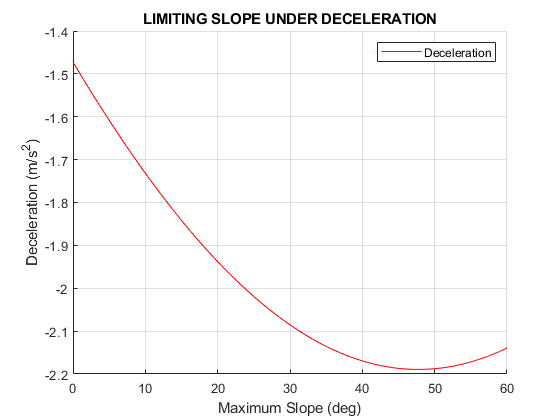

figure
hold on
plot(theta,dvdt_d,'red')
hold off
xlabel('Maximum Slope (deg)')
ylabel("Deceleration (m/s^2)")
legend('Deceleration')
grid on
title('LIMITING SLOPE UNDER DECELERATION')

### Impulsive Pitch-over Criteria


$$V_{limit} \leq \sqrt{2g(\sqrt{a^2+h^2} -h)}$$


v_limit = sqrt(2*g*(sqrt(a_^2+h_^2)-h_));
V_limit = [num2str(v_limit),'  m/s'];
disp(V_limit)

1.2479  m/s


### Turning radius on a slope

$radius = \frac{v^2}{g}[\frac{y.cos{\theta}}{h} - sin{\theta}]^{-1}$, where v is the velocity of the vehicle

% theta = 20;
% v_limit =1.2479;
% y_ = 0:0.1:5;
% for i = 1:length(y_)
%     radius = (v_limit^2/g)*((y_(i)/h_).*cosd(theta) - sind(theta)).^(-1);
%     figure(1)
%     hold on
%     plot(y_(i),radius,'blue')
%     hold off
%     xlabel('Maximum Slope (deg)')
%     ylabel('Velocity (m/s)')
%     ylim([0 1])
%     grid on
%     title('Turning Radius on Slope')
% end
% radius = (v_limit^2/g).*((y_/h_).*cosd(theta) - sind(theta)).^(-1);
% figure
% hold on
% plot(y_,radius,'blue')
Radius = [num2str(radius),'  m  (radius based on V_limit)'];
disp(Radius)

0.17379  m  (radius based on V_limit)
